# Antenna Frequency Response Report Generator

## 1 Configuration

clear;
close all;
clc;
clf;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

dir_output = "../inout_sps";
filenames_toload = ["20230107_L10_LowHeight_Dipole_v6.5ASYN.s1p";"20221231_L10_LowHeight_Dipole_v6.5_01.s1p"];
savefile_types = [".png"; ".fig"; ".emf";];                     % .csv has a matrix bug.
alternate_filenames = ["LowHeight\_Dipole\_v6.5ASYN";"LowHeight\_Dipole\_v6.5\_01";];
cmdColorOrder = [1 0 0; 0 0 1; 0.4660 0.6740 0.1880];           % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html
cmdLineStyleOrder = ["-" "-" "-"];
cmdLineWidthOrder = [1.5; 1.5; 1.5];
cmdXlim_GHz = [1;10];
cmdStyles="ieee";

## 2 Return Loss [dB]

cmd_genfig_s11_logmag(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder);

## 3 VSWR

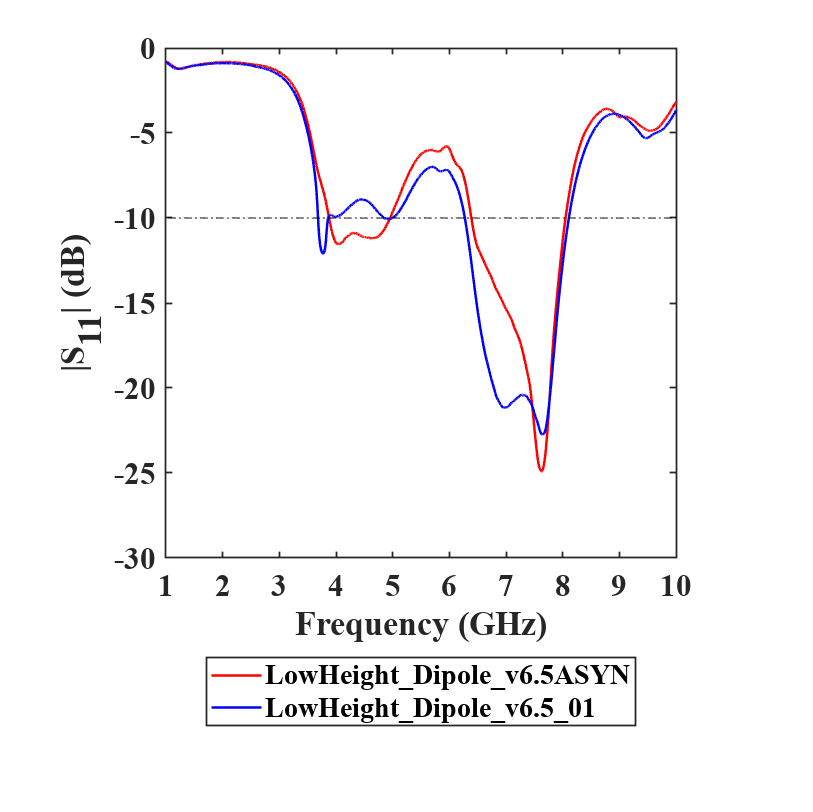

cmd_genfig_s11_vswr(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder, "none");

## 4 Z Parameters

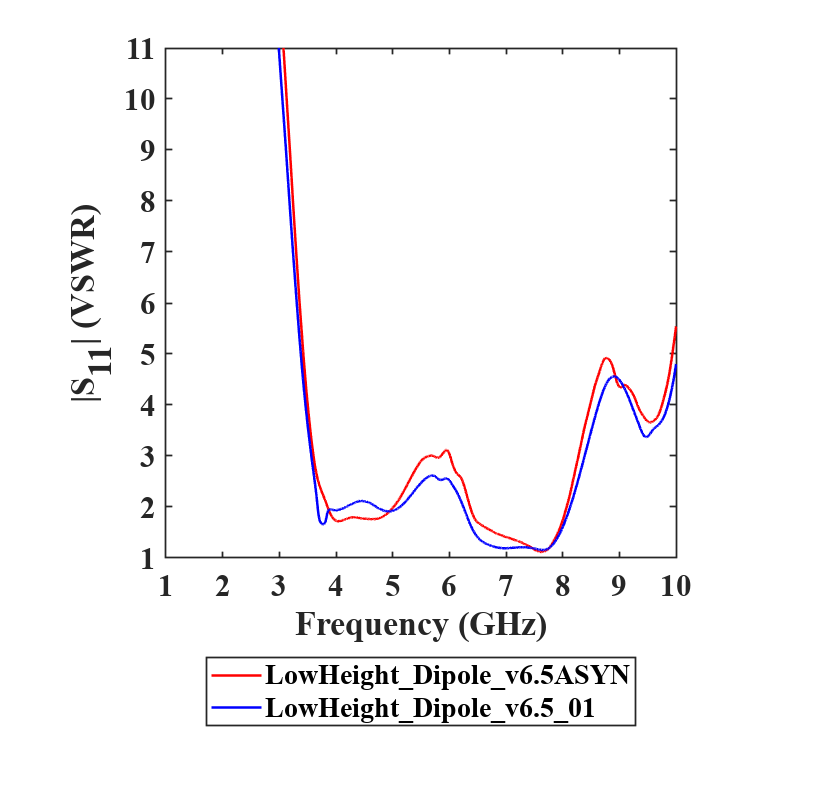

cmd_genfig_s11_zparam(dir_output, filenames_toload(1), cmdXlim_GHz, cmdStyles, savefile_types, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder);

## 5 S11 Smith Chart (full-range)

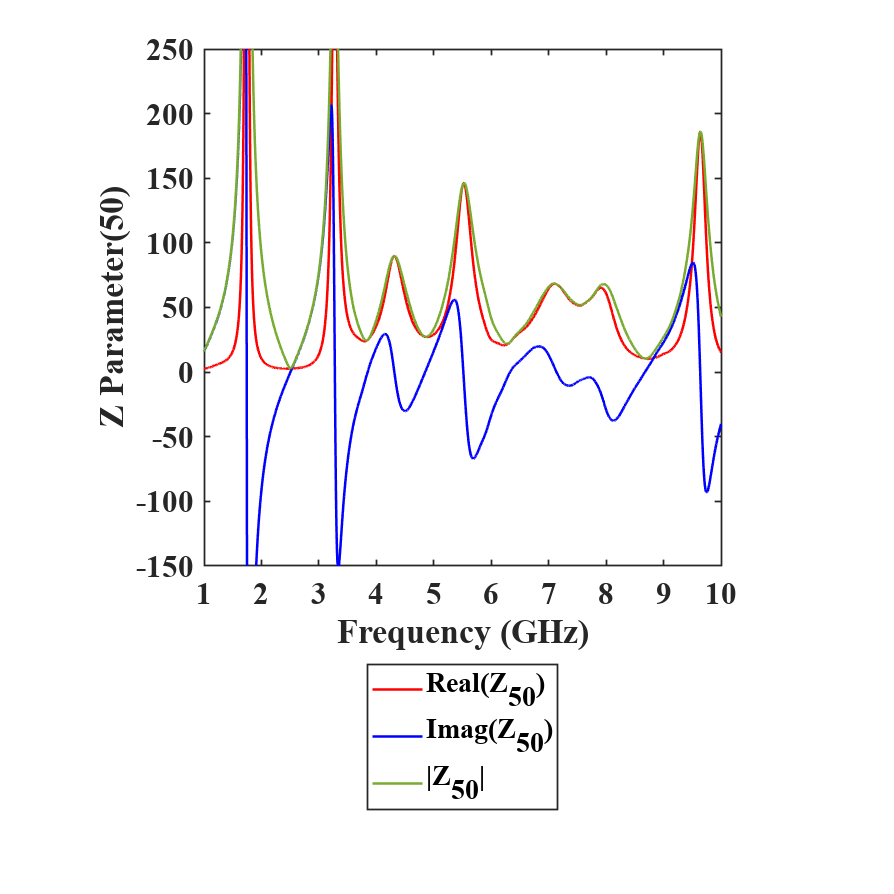

cmd_genfig_s11_smith(dir_output, filenames_toload(1), "auto", cmdXlim_GHz, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 6 S11 Smith Chart (reduced-range)

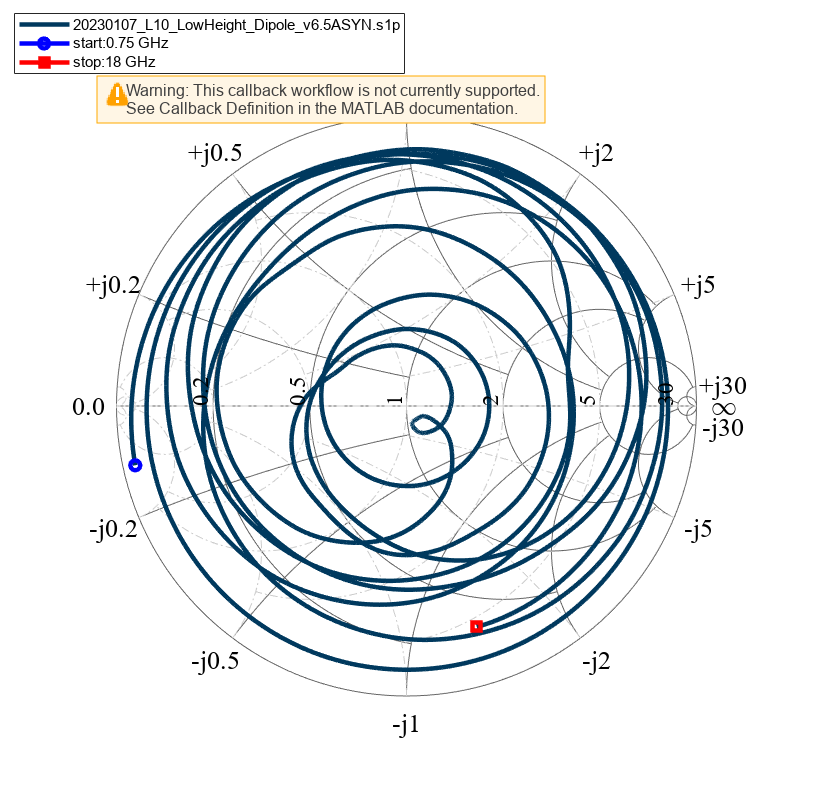

cmd_genfig_s11_smith(dir_output, filenames_toload(1), "man", [1.5;2.5], cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

% error: creating .csv file.. cmd_genfig_s11_smith(dir_output, filenames(1), "man", [1.5;2.5], cmdStyles, [".csv";".png"], cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 7 S11 Phase (unwrapped)

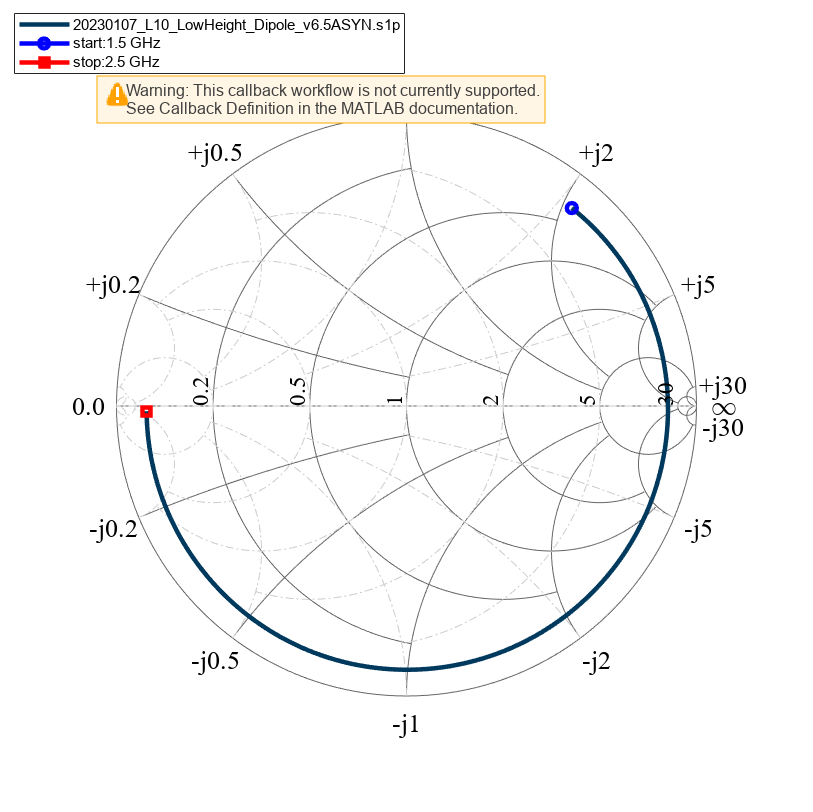

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,1);

## 8 S11 Phase (wrapped)

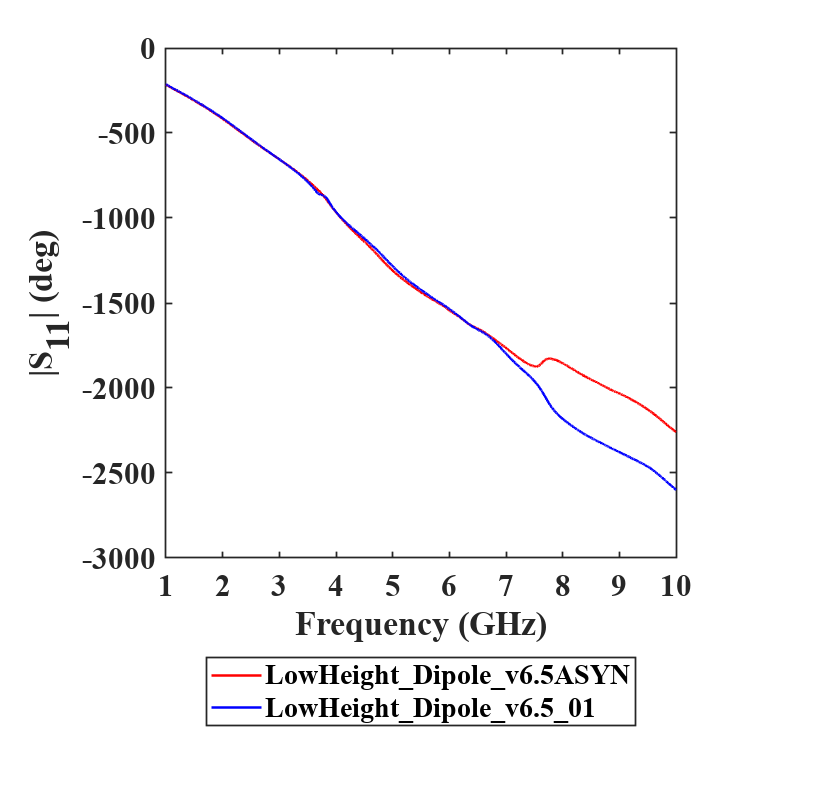

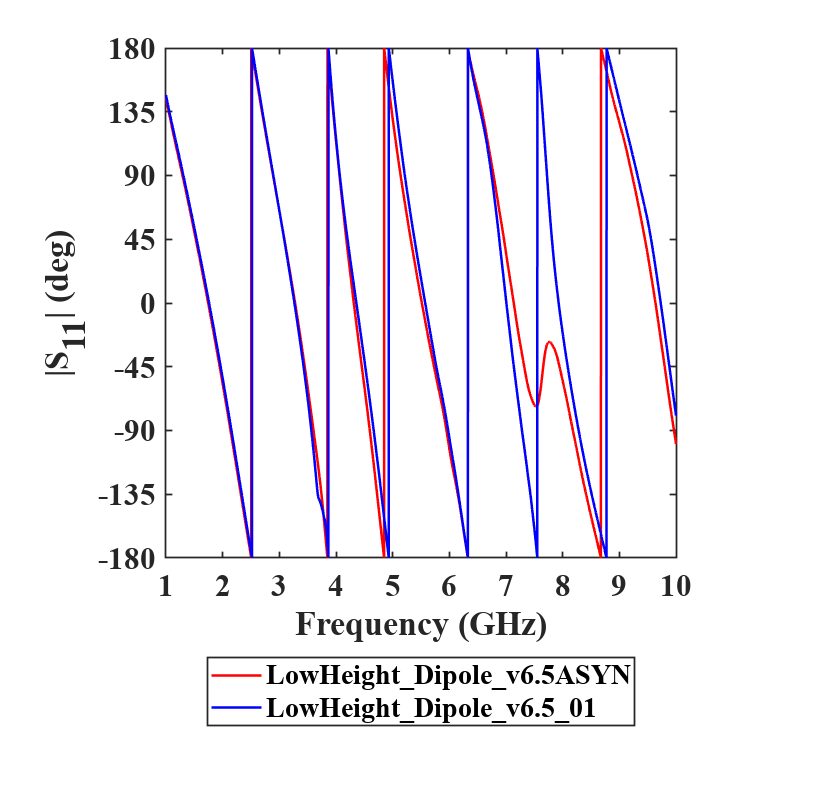

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,0);